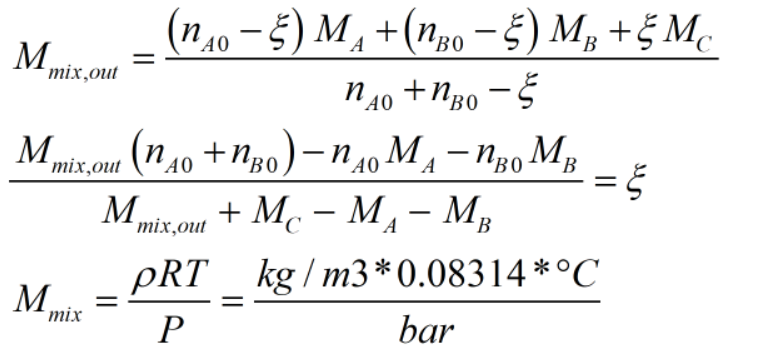

% Importar datos y cambiar encabezados
DataSet = readtable("MatLabVer-AVEVA_2026AcademicCompetition_AllData.xlsx")

DataSet = 3066×51 table
               Timestamp                AT_1100_PVValueKg_m3    AT_1104_PVValueKg_m3    AT_1201_PVValueKg_m3    FC_1002_PVValueKg_h    FC_1002_SPValueKg_h    FRC_1004_PVValue    FRC_1004_SPValue    FT_1001_PVValueKg_h    FT_1002_PVValueKg_h    FT_1003_PVValueKg_h    FT_1004_PVValueKg_h    FT_1005_PVValueKg_h    FT_1102_PVValueM3_h    FT_1104_PVValueM3_h    FT_1200_PVValueKg_h    FT_1201_PVValueKg_h    FT_1215_PVValueKg_h    FT_1300_PVValueKg_h    LC_1001_PVValue_    LC_1001_SPValue_    LC_1104_PVValue_    LC_1104_SPValue_    LC_1200_PVValue_    LC_1200_S

Header = DataSet.Properties.VariableNames;
Header = regexprep(Header,'Value.*$','');
Header = regexprep(Header,'[^a-zA-Z0-9]','');
DataSet.Properties.VariableNames = Header;

% Convertir el timestamp string a datetime
DataSet.Timestamp = datetime(DataSet.Timestamp,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSSSSS''Z''','TimeZone',"UTC");
TimedDataSet = table2timetable(DataSet)

TimedDataSet = 3066×50 timetable
         Timestamp          AT1100PV    AT1104PV    AT1201PV    FC1002PV    FC1002SP    FRC1004PV    FRC1004SP    FT1001PV    FT1002PV    FT1003PV    FT1004PV    FT1005PV    FT1102PV    FT1104PV    FT1200PV    FT1201PV    FT1215PV    FT1300PV    LC1001PV    LC1001SP    LC1104PV    LC1104SP    LC1200PV    LC1200SP    LC1212PV    LC1212SP    PC1104PV    PC1104SP    PT1001PV    PT1004PV    PT1100PV    PT1300PV

% Densidad: B-D (1-3) kg/m3
Densidad = TimedDataSet(:,1:3)

Densidad = 3066×3 timetable
         Timestamp          AT1100PV    AT1104PV    AT1201PV
    ____________________    ________    ________    ________

    12-Oct-2025 15:00:00     37.378      797.95      730.84 
    12-Oct-2025 15:01:00     37.378      797.95      730.84 
    12-Oct-2025 15:02:00     37.378      797.95      730.84 
    12-Oct-2025 15:03:00     37.378      797.95      730.84 
    12-Oct-2025 15:04:00     37.378      797.95      730.84 
    12-Oct-2025 15:05:00     37.378      797.95      730.84 
    12-Oct-2025 15:06:00     37.378      797.95      730.84 
    12-Oct-2025 15:07:00     37.378      797.95      730.84 
    12-Oct-2025 15:08:00     37.378      797.95      730.84 
    

% Flujo: E-S (4-18) kg/h
Flujo = TimedDataSet(:,4:18)

Flujo = 3066×15 timetable
         Timestamp          FC1002PV    FC1002SP    FRC1004PV    FRC1004SP    FT1001PV    FT1002PV    FT1003PV    FT1004PV    FT1005PV    FT1102PV    FT1104PV    FT1200PV    FT1201PV    FT1215PV    FT1300PV
    ____________________    ________    ________    _________    _________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________

    12-

% Nivel: T-AA (19-26) %
Nivel = TimedDataSet(:,19:26)

Nivel = 3066×8 timetable
         Timestamp          LC1001PV    LC1001SP    LC1104PV    LC1104SP    LC1200PV    LC1200SP    LC1212PV    LC1212SP
    ____________________    ________    ________    ________    ________    ________    ________    ________    ________

    12-Oct-2025 15:00:00       50          50          50          50          50          50          50          50   
    12-Oct-2025 15:01:00       50          50          50          50          50          50          50          50   
    12-Oct-2025 15:02:00       50          50          50          50          50          50          50          50   
    

% Presión: AB-AG (27-32) kPa
Presion = TimedDataSet(:,27:32)

Presion = 3066×6 timetable
         Timestamp          PC1104PV    PC1104SP    PT1001PV    PT1004PV    PT1100PV    PT1300PV
    ____________________    ________    ________    ________    ________    ________    ________

    12-Oct-2025 15:00:00     215.71      215.71      2623.9      2575.8      2521.6      2627.2 
    12-Oct-2025 15:01:00     215.71      215.71      2623.9      2575.8      2521.6      2627.2 
    12-Oct-2025 15:02:00     215.71      215.71      2623.9      2575.8      2521.6      2627.2 
    12-Oct-2025 15:03:00     215.71      215.71      2623.9      2575.8      2521.6      2627.2 
    12-Oct-2025 15:04:00     215.71      215.71      2623.9      25

% Temperatura: AH-AY (33-50) °C
Temperatura = TimedDataSet(:,33:50)

Temperatura = 3066×18 timetable
         Timestamp          TC1006PV    TC1006SP    TC1103PV    TC1103SP    TC1205PV    TC1205SP    TC1211PV    TC1211SP    TC1215PV    TC1215SP    TT1001PV    TT1004PV    TT1005PV    TT1006PV    TT1100PV    TT1102PV    TT1103PV    TT1211PV
    ____________________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ___

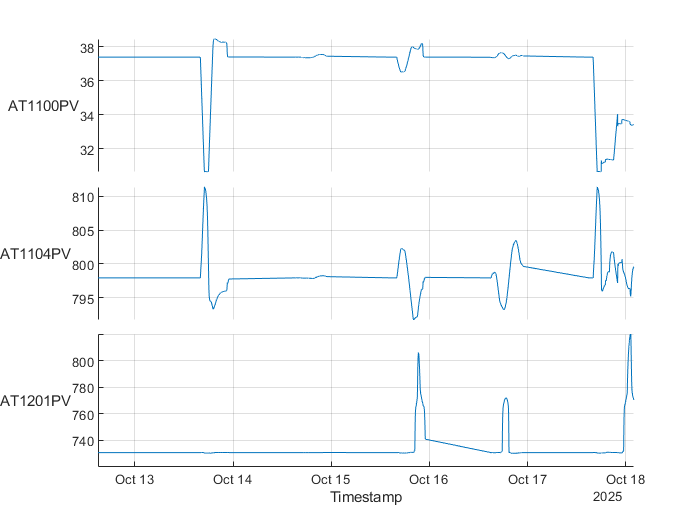

figure;
D = stackedplot(Densidad);
D.AxesProperties(3).YLimits = [720 820];
D.GridVisible = 'on';

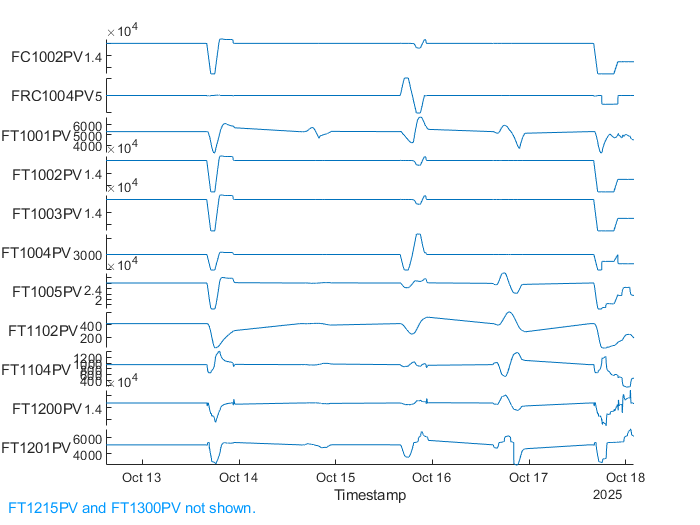

figure;
F = stackedplot(Flujo(:,Flujo.Properties.VariableNames(~endsWith(Flujo.Properties.VariableNames,'SP'))));

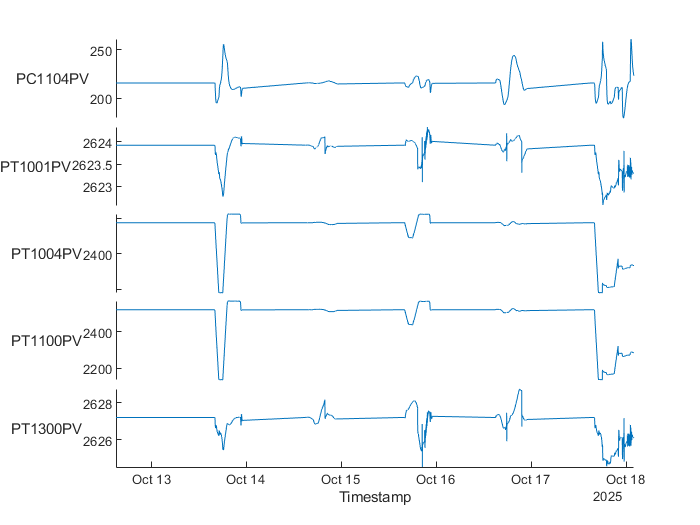

figure;
P = stackedplot(Presion(:,Presion.Properties.VariableNames(~endsWith(Presion.Properties.VariableNames,'SP'))));

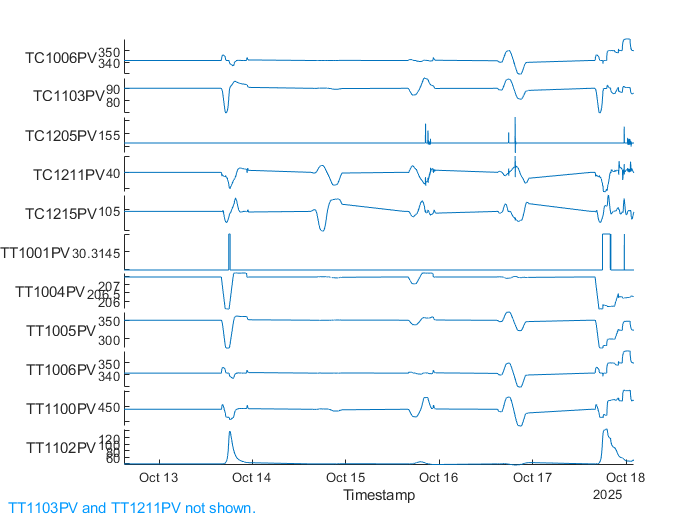

figure;
T = stackedplot(Temperatura(:,Temperatura.Properties.VariableNames(~endsWith(Temperatura.Properties.VariableNames,'SP'))));

$X_{\textrm{propeno}} =\frac{\nu_A \xi }{-n_{\textrm{A0}} }$    ,    $A+B\longrightarrow C$    ,   $M=\frac{m}{n}$

% Obtener Conversion
% Variables a usar para M_salida: FT1002, FT1004, TT1006
% Variables a usar M_teórico: TT1100, AT1100, PT1100
% Propiedades de Benzene (Be, B), Propene (Pr, A) y Cumene (Cu, C):

Mi =  [42.081 78.11 120.19]; % A, B, C. kg/kmol
Nui = [-1 -1 1]; % A, B, C
nA0 = Flujo.FT1004PV/Mi(1);     % kmol/h
nB0 = Flujo.FT1002PV/Mi(2);     % kmol/h
Mmix_teo = (Densidad.AT1100PV.*0.08314.*(Temperatura.TT1100PV+273.15))./(Presion.PT1100PV/100); % kg/kmol
Ext = (Mmix_teo.*(nA0+nB0)-nA0.*Mi(1)-nB0.*Mi(2))./(Mmix_teo+Mi(3)-Mi(1)-Mi(2));
XA = Nui(1).*Ext./(-nA0);

RxInOutResults = TimedDataSet(:, {'FT1002PV','TT1100PV'});
RxInOutResults.Ext = Ext;
RxInOutResults.XA = XA

RxInOutResults = 3066×4 timetable
         Timestamp          FT1002PV    TT1100PV     Ext        XA   
    ____________________    ________    ________    ______    _______

    12-Oct-2025 15:00:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:01:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:02:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:03:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:04:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:05:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:06:00     15000       440.57     58.689    0.82322
    12-Oct-2025 15:07:00     

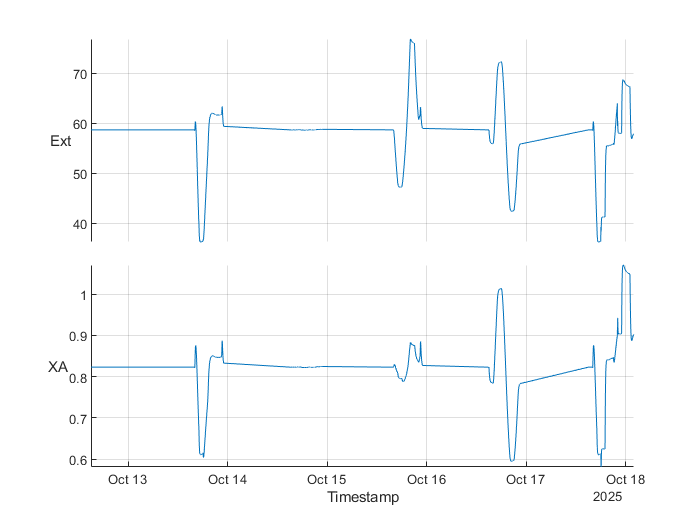

figure;
Res = stackedplot(RxInOutResults,["Ext" "XA"]);
Res.GridVisible = 'on';

maxXa = [max(XA) min(XA)]

maxXa =     1.0708    0.5812


cant = numel(XA)

cant = 3066

cantMax = sum(XA>1)

cantMax = 183